# Ex_05 气垫导轨

## 表 2

data = [
1591.20	1595.08	1594.49	1594.16
1591.31	1595.00	1594.69	1594.09
1591.30	1595.04	1594.64	1594.28
1591.30	1594.76	1594.36	1594.35
1591.37	1594.92	1594.35	1594.42    
];
data = [
data
mean(data)
];
%MyPrint_xlsx(data, 2)
vpa(mean(data(end, :)))

## 表 3

data = [
1593.83	1637.80	1721.70	1762.28	1840.45
1593.88	1637.95	1721.68	1761.72	1840.69
1594.13	1638.06	1721.74	1762.04	1840.55
1594.16	1638.07	1721.76	1762.34	1840.54
1594.30	1638.12	1721.92	1762.39	1840.62
1594.20	1638.29	1722.05	1762.74	1840.69
1594.12	1638.38	1721.99	1762.72	1840.82
1594.18	1638.51	1722.45	1762.6	1840.81
1594.34	1638.36	1721.84	1762.72	1840.73
1594.40	1638.50	1722.15	1762.72	1840.86   
];
data = [
data
mean(data)
];
%MyPrint_xlsx(data, 2)


m = [220.60, 12.54, 24.94, 12.49, 24.97];
for i = 1:5
    X(i) = sum(m(1:i));
end
Y = data(end, :).^2;
stc = MyFit_linear(X, Y);
stc.label.x.String = '$m$ (g)';
stc.label.y.String = '$T^2\ (\mathrm{(ms)}^2)$ ';
%MyExport_pdf_docked

k = 4*pi^2/11.296
m_0 = 0.049812*k/(4*pi^2)*1000

## 表 4

data = [
148.37	141.64	132.98	120.05	100.30
148.81	142.25	132.80	121.31	98.66
148.59	142.65	132.62	119.90	100.00
];
data = [
data
mean(data)
];
%MyPrint_xlsx(data, 2)
X = ((10:5:30)*0.01).^2;
Y = (data(end, :)*0.01).^2;
stc = MyFit_linear(X, Y);
stc.label.x.String = '$x^2\ \mathrm{(m^2)} $';
stc.label.y.String = '$v^2\ \mathrm{(m^2/s^2)} $';
%MyExport_pdf_docked
omega_0 = sqrt(15.049)
T = vpa(2*pi/omega_0)*1000

## 表 5

data = [
148.37	141.64	132.98	120.05	100.30
148.81	142.25	132.80	121.31	98.66
148.59	142.65	132.62	119.90	100.00
];

m = (220.60 + 4.4097)*10^(-3)
vpa(m*1000)
k
data = mean(data)*0.01;
data = [
((10:5:30)*0.01).^2
data
0.5*m*data.^2
0.5*k*((10:5:30)*0.01).^2
];

data = [
data
data(3, :) + data(4, :) 
]
%MyPrint_xlsx(data, 4)
stc = MyPlot(data(1, :), [data(5, :); data(3, :); data(4, :)]);
stc.leg.String = ["$y = E$"; "$y = E_k$"; "$y = E_p$"; ]
stc.label.x.String = '$x$ (m)';
stc.label.y.String = '$y$ (J)';
%MyExport_pdf_docked

## 表 6

data = [
38.90	57.64	76.92	96.34	115.47
39.09	57.67	76.80	96.33	115.21
39.21	57.87	77.04	96.25	115.2    
];

data = [
(10:5:30)
data
mean(data)
];
%MyPrint_xlsx(data, 2)

stc = MyFit_proportional((data(1, :)*0.01).^2, (data(end, :)*0.01).^2);
stc.label.x.String = '$A^2\ (\mathrm{m^2})$';
stc.label.y.String = '$v_{\max}^2\ (\mathrm{m^2/s^2})$';

X = (data(1, :)*0.01).^2;
Y =  (data(end, :)*0.01).^2;
%MyExport_pdf_docked

a = 14.796;
k = m*a

220.60 - 2.61

## 表 8

data = [
27.62	27.53	27.59	27.79	27.79
81.29	81.70	81.3	81.70	81.41
135.22	135.17	135.57	135.61	135.51
262.67	262.40	263.47	262.62	263.20
];
h = [1;3;5;10];
data = [
data, mean(data, 2), h*0.01./(mean(data, 2)*0.001)
];

MyPrint_xlsx(data, 4)

ans = 4×7 cell 数组
    {'27.6200' }    {'27.5300' }    {'27.5900' }    {'27.7900' }    {'27.7900' }    {'27.6640' }    {'0.3615'}
    {'81.2900' }    {'81.7000' }    {'81.3000' }    {'81.7000' }    {'81.4100' }    {'81.4800' }    {'0.3682'}
    {'135.2200'}    {'135.1700'}    {'135.5700'}    {'135.6100'}    {'135.5100'}    {'135.4160'}    {'0.3692'}
    {'262.6700'}    {'262.4000'}    {'263.4700'}    {'262.6200'}    {'263.2000'}    {'262.8720'}    {'0.3804'}



stc = MyFit_linear(data(:, end-1)*0.001, data(:, end)');

y = ax + b
a = 7.6696e-02
b = 3.6010e-01
R^2  = 0.9700916
SSE  = 5.52615e-06
RMSE = 1.66225e-03


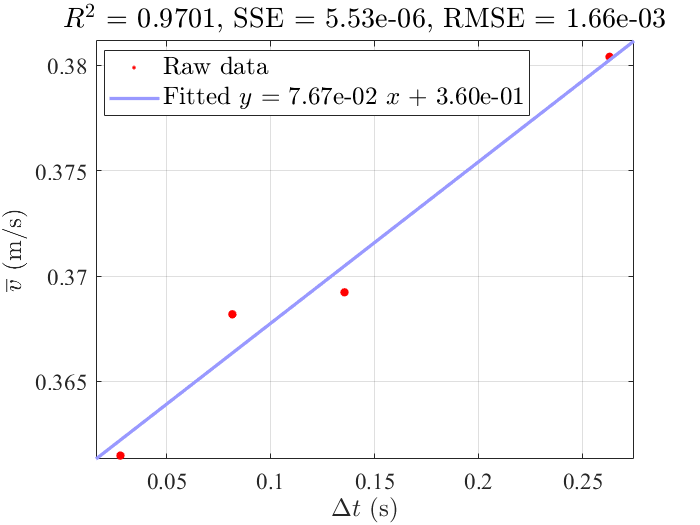

stc.label.x.String = '$\Delta t\ (\mathrm{s})$';
stc.label.y.String = '$\overline{v}\ (\mathrm{m/s})$';
%MyExport_pdf_docked

## 表 9

data = [
20.36	20.30	20.31	20.38	20.32
60.01	60.22	60.20	60.19	60.15
99.80	100.05	99.86	100.10	99.96
195.24	195.10	195.52	195.70	195.22
];
h = [1;3;5;10];
data = [
data, mean(data, 2), h*0.01./(mean(data, 2)*0.001)
];

MyPrint_xlsx(data, 4)

ans = 4×7 cell 数组
    {'20.3600' }    {'20.3000' }    {'20.3100' }    {'20.3800' }    {'20.3200' }    {'20.3340' }    {'0.4918'}
    {'60.0100' }    {'60.2200' }    {'60.2000' }    {'60.1900' }    {'60.1500' }    {'60.1540' }    {'0.4987'}
    {'99.8000' }    {'100.0500'}    {'99.8600' }    {'100.1000'}    {'99.9600' }    {'99.9540' }    {'0.5002'}
    {'195.2400'}    {'195.1000'}    {'195.5200'}    {'195.7000'}    {'195.2200'}    {'195.3560'}    {'0.5119'}



stc = MyFit_linear(data(:, end-1)*0.001, data(:, end)');

y = ax + b
a = 1.0986e-01
b = 4.9033e-01
R^2  = 0.9762632
SSE  = 4.95383e-06
RMSE = 1.57382e-03


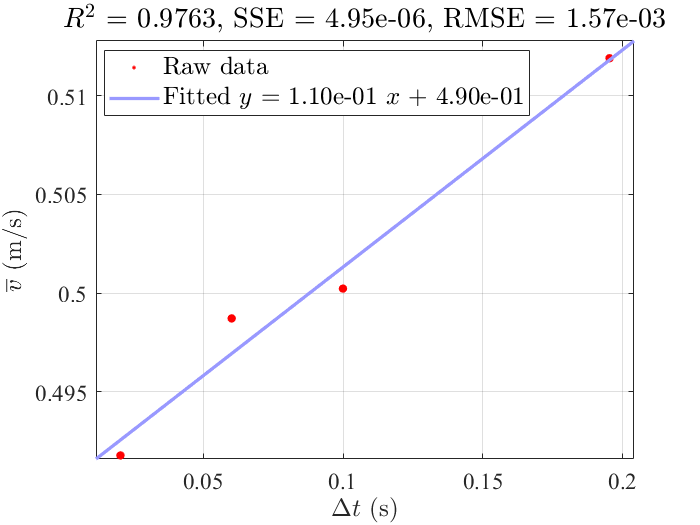

stc.label.x.String = '$\Delta t\ (\mathrm{s})$';
stc.label.y.String = '$\overline{v}\ (\mathrm{m/s})$';
%MyExport_pdf_docked

## 表 10

data = [
18.54	18.56	18.56	18.52	18.53
54.85	54.98	54.82	54.95	54.96
91.47	91.44	91.18	91.17	91.40
179.12	179.54	179.28	179.52	179.22
];
h = [1;3;5;10];
data = [
data, mean(data, 2), h*0.01./(mean(data, 2)*0.001)
];

MyPrint_xlsx(data, 4)

ans = 4×7 cell 数组
    {'18.5400' }    {'18.5600' }    {'18.5600' }    {'18.5200' }    {'18.5300' }    {'18.5420' }    {'0.5393'}
    {'54.8500' }    {'54.9800' }    {'54.8200' }    {'54.9500' }    {'54.9600' }    {'54.9120' }    {'0.5463'}
    {'91.4700' }    {'91.4400' }    {'91.1800' }    {'91.1700' }    {'91.4000' }    {'91.3320' }    {'0.5475'}
    {'179.1200'}    {'179.5400'}    {'179.2800'}    {'179.5200'}    {'179.2200'}    {'179.3360'}    {'0.5576'}



stc = MyFit_linear(data(:, end-1)*0.001, data(:, end)');

y = ax + b
a = 1.0746e-01
b = 5.3843e-01
R^2  = 0.9656900
SSE  = 5.84940e-06
RMSE = 1.71018e-03


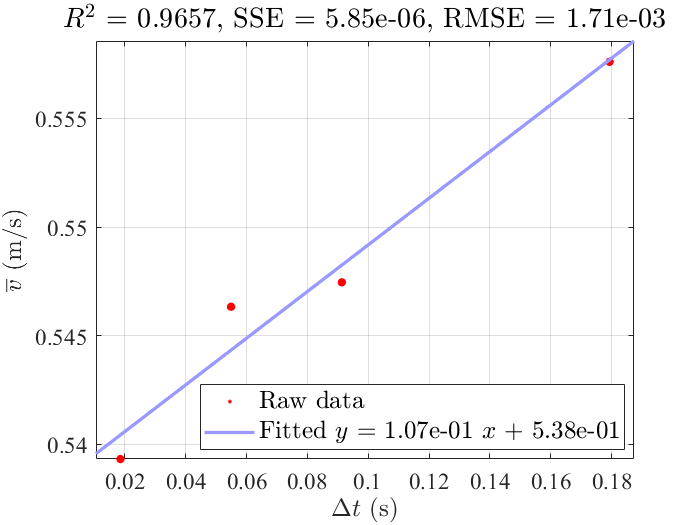

stc.label.x.String = '$\Delta t\ (\mathrm{s})$';
stc.label.y.String = '$\overline{v}\ (\mathrm{m/s})$';
%MyExport_pdf_docked

## 粘度系数

data = [
25.10	25.53	25.50	25.31	25.55
19.52	19.47	19.44	19.47	19.20
14.87	14.06	14.31	14.077	14.16
10.41	10.03	10.09	10.10	10.00
7.44	7.41	7.31	7.28	7.34
5.60	5.50	5.50	5.50	5.47
4.13	4.18	4.20	4.19	4.18
];

eta_0 = [0.621; 0.451; 0.312; 0.231; 0.172; 0.126; 0.098]

eta_0 =     0.6210
    0.4510
    0.3120
    0.2310
    0.1720
    0.1260
    0.0980


D = 0.2;
v_0 = 0.2./mean(data, 2)

v_0 =     0.0079
    0.0103
    0.0140
    0.0198
    0.0272
    0.0363
    0.0479


g = 9.8015;
rho = 7.8e3;
rho_0 = 0.95e3;
d=1.12e-3

d = 0.0011

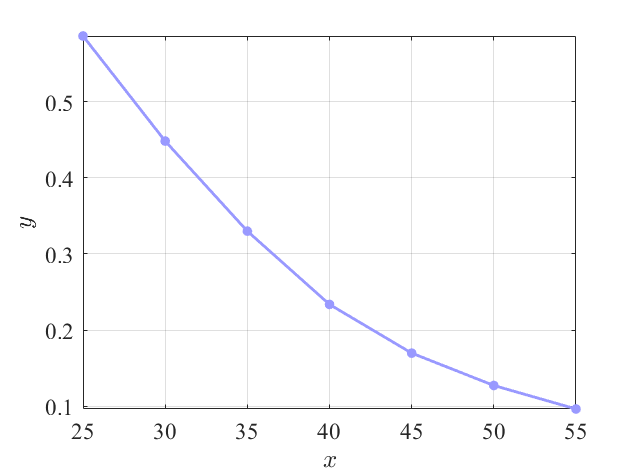

ans = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


eta = d^2*g*(rho-rho_0)./(18*v_0*(1 + 2.4*d/D));

data=[
data, mean(data, 2), v_0, eta, eta_0, MyGet_eta(eta_0, eta)*100
];

%MyPrint_xlsx(data, 4)

MyPlot(25:5:55, eta')

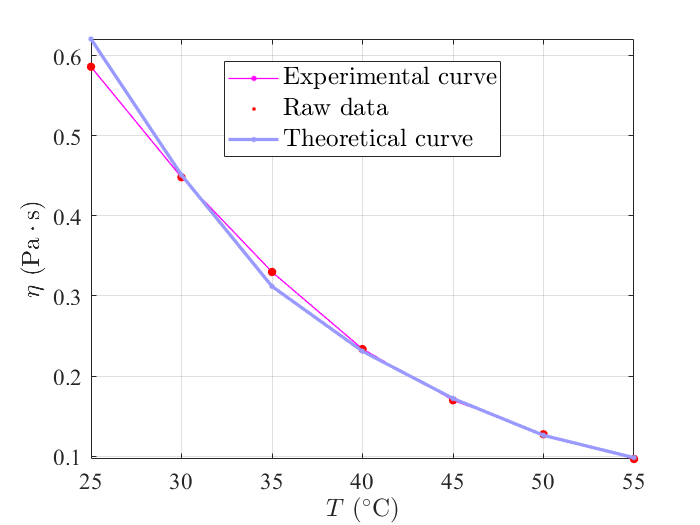


stc = MyPlot_TheoAndExpe(25:5:55, eta', eta_0');
stc.leg.String = [ "Experimental curve"; "Raw data"; "Theoretical curve" ];
stc.label.x.String = '$T\ \mathrm{(^\circ C)}$';
stc.label.y.String = '$\eta\ \mathrm{(Pa \cdot s)}$';
%MyExport_pdf_docked